# Practical 10

## Question Form

Maleic Anhydride (MA) is industrially produced by the oxidation of the n-butene. The n-butene diluted in air is fed to a fluidized bed reactor filled with Geldart A particles. In this condition, the solid particles are well mixed into the system allowing isothermal operations. As a first approximation, assume a CSTR behavior of the gas in the emulsion phase. Details of the configuration, catalysts, and operating conditions are given below. The reaction network is given by the following three reactions:


$$\begin{array}{l}
C_4 H_{10} +3\ldotp 5O_2 \to C_4 H_2 O_3 +4H_2 O\;\;\;\left(1\right)\\
C_4 H_{10} +5\ldotp 5O_2 \to 2\mathrm{CO}+5H_2 O\;\;\;\left(2\right)\\
C_4 H_2 O_3 +O_2 \to 4\mathrm{CO}+H_2 O\;\;\;\left(3\right)
\end{array}$$


The system can be considered a mixture of ideal gases. Considering a three-phase Kunii-Levenspiel model:

- Calculate the value of the minimum fluidization velocity and the maximum fluidization ratio that can be adopted for this system.

- Calculate the pressure drops across the reactor.

- Calculate the fraction of the molar gas flow rate in the bubble phase.

- Report the mass fraction profile of the n-butene in the bubble, cloud, and emulsion phases along the tube (report the qualitative graph with the values at 0.5, 1, 2, and 2.5 m).

- Assess if slugging mode can occur in the reactor.

- Assess what would be the impact on the outlet conversion in case the gas in the emulsion is considered to be static.

## Theory

The starting point of fluidization is when the drag force equals the particle weight ($F_D =m_p g$)

The Ergun equation for fluidized bed expressed as follows:


$$\begin{array}{l}
\left\lbrace \begin{array}{ll}
\frac{\Delta P}{L_{\mathrm{mf}} }=\left(1-\varepsilon_{\mathrm{mf}} \right)\left(\rho_s -\rho_g \right)g & \\
\frac{\Delta P}{L_{\mathrm{mf}} }=\frac{m_{\mathrm{cat}} \ldotp g}{\mathrm{AL}} & 
\end{array}\right.\\
\frac{\Delta P}{L_{\mathrm{mf}} }=150\;\frac{{\left(1-\varepsilon_{\mathrm{mf}} \right)}^2 }{\varepsilon_{\mathrm{mf}} }\ldotp \frac{\mu v_{\mathrm{mf}} }{d_p^2 }+\frac{7}{4}\;\frac{\left(1-\varepsilon_{\mathrm{mf}} \right)}{\varepsilon_{\mathrm{mf}}^3 }\ldotp \frac{{\rho_g v}_{\mathrm{mf}}^2 }{d_p }
\end{array}$$


The force balance for a particle in fluidization mode is written as follows:


$$\begin{array}{l}
V_p \left(\rho_p -\rho_g \right)g-\frac{1}{2}\rho_g v^2 A_p C_d =0\\
A_p =\frac{\pi \;d_p }{4}\\
\mathrm{for}\;{\mathrm{Re}}_p <0\ldotp 4\Rightarrow C_d =\frac{24}{{\mathrm{Re}}_p }\\
\mathrm{for}\;{\mathrm{Re}}_p \ge 0\ldotp 4\Rightarrow C_d =\frac{24}{{\mathrm{Re}}_p }\left(1+0\ldotp 15{\mathrm{Re}}_p^{0\ldotp 687} \right)
\end{array}$$


Usually, the $\frac{v_t }{v_{\mathrm{mf}} }$ is in the range [10,90]

The ergun equation can be considered as polynomial:


$$\begin{array}{l}
\frac{\mathrm{mg}}{{\mathrm{AL}}_{\mathrm{mf}} }-150\;\frac{{\left(1-\varepsilon_{\mathrm{mf}} \right)}^2 }{\varepsilon_{\mathrm{mf}}^3 }\;\frac{\mu }{d_p^2 }\times v_{\mathrm{mf}} +\frac{7}{4}\;\frac{\left(1-\varepsilon_{\mathrm{mf}} \right)}{\varepsilon_{\mathrm{mf}}^3 }\ldotp \frac{\rho_g }{d_p }\times v_{\mathrm{mf}}^2 =0\\
\frac{7}{4}\;\frac{\left(1-\varepsilon_{\mathrm{mf}} \right)}{\varepsilon_{\mathrm{mf}}^3 }\ldotp \frac{\rho_g }{d_p }=A\\
-150\;\frac{{\left(1-\varepsilon_{\mathrm{mf}} \right)}^2 }{\varepsilon_{\mathrm{mf}}^3 }\;\frac{\mu }{d_p^2 }=B\\
\frac{\mathrm{mg}}{{\mathrm{AL}}_{\mathrm{mf}} }=C\\
{\mathrm{Av}}_{\mathrm{mf}}^2 +{\mathrm{Bv}}_{\mathrm{mf}} +C=0
\end{array}$$


## Initial Data

close all, clear, clc

global NS NP L NTOT delta_z z_star v_bubble v_mf omega_0 v_0 delta integral ...
    yp_bubble rho_0 MW epsi_mf v_single_bubble d_bubbles g diffusivity ...
    k_bc k_ce P0 T0 catalyst_density Rate_emulsion Rate_bubble Rate_cloud ...
    gamma_b gamma_c gamma_e f_cl f_w

%% OPERATING CONDITIONS
%species order
%1)n-butane 2)O2 3)MA 4)CO 5)CO2 6)H2O 7)N2

MW=[58;32;98;28;44;18;28];   % [kg/kmol] 
NS=length(MW); % number of species
N_phases = 3; % number of phases
n_butane_to_air_ratio_molar=0.04;
n_0=[n_butane_to_air_ratio_molar;0.21;0;0;0;0;0.79];
x_0=n_0/sum(n_0); % [-] inlet molar fractions
mass_0=n_0.*MW;
omega_0=mass_0/sum(mass_0); % [-] inlet species mass fraction vector

MWmix=0;
for k=1:NS
   MWmix=MWmix+x_0(k)*MW(k); 
end

P0=101325;  % [Pa] 
T0=430+273.15;     % [K] temperature of the gas feed
rho_0=P0/8314/T0*MWmix;   % [kg/m3] density of the inlet gas feed
v_0=0.25;     % [m/s] inlet superficial velocity

%% CATALYST PROPERTIES
catalyst_density=1200; %[kg/m3]
mcat=27318; %[kgcat]
dp=0.000125; %[m]

%% GAS PROPERTIES
diffusivity=3e-5; % [m2/s]
viscosity=3.28e-5; % [Pa*s]

%% REACTOR
d_reactor=5; % [m]
A_reactor = pi*d_reactor^2/4; % m2

%% CONSTANTS
g=9.81; % [m/s2] 

%% BUBBLING FLUIDIZED BED PARAMETERS
d_bubbles=0.05; %[m] assumed constant for Geldart A particles
epsi_mf=0.42; % minimum fluidization void fraction
v_mf=0.0048;     % [m/s] minimum fluidization velocity
v_single_bubble=0.711*(g*d_bubbles)^0.5; % single bubble rise velocity
v_bubble=(v_0-v_mf)+v_single_bubble; % rise velocity of bubbles in swarm

f_cl=3*(v_mf/epsi_mf)/(v_bubble-(v_mf/epsi_mf)); % volume of cloud/volume of bubble
f_w=0.2; % volume of wake/volume of bubble

gamma_b=0.005; %volume of particles in bubbles/volume of bubbles
delta=(v_0-v_mf)/(v_bubble-(1+(f_cl+f_w))*v_mf); %volume of bubbles/volume of fluidized bed

gamma_c=(1-epsi_mf)*(f_cl+f_w); %volume of particles in cloud+wake/volume of bubbles
gamma_e=(1-epsi_mf)*(1-delta)/delta-gamma_c; %volume of particles in emulsion/volume of bubbles

epsi_bed=1-(delta*gamma_b+(1-delta)*(1-epsi_mf)); %volume of void/volume of fluidized bed reactor
L=mcat/(catalyst_density*(pi*d_reactor^2/4)*(1-epsi_bed)); %fluidized bed average bed height

V_reactor = A_reactor*L; % m3
V_bubble = V_reactor*delta; % m3
V_emulsion = V_reactor-V_bubble-V_bubble*(f_cl+f_w); % m3

## BUBBLING FLUIDIZED BED PARAMETERS

d_bubbles=0.05; %[m] assumed constant for Geldart A particles
epsi_mf=0.42; % minimum fluidization void fraction
v_mf=0.0048;     % [m/s] minimum fluidization velocity
v_single_bubble=0.711*(g*d_bubbles)^0.5; % single bubble rise velocity
v_bubble=(v_0-v_mf)+v_single_bubble; % rise velocity of bubbles in swarm

f_cl=3*(v_mf/epsi_mf)/(v_bubble-(v_mf/epsi_mf)); % volume of cloud/volume of bubble
f_w=0.2; % volume of wake/volume of bubble

gamma_b=0.005; %volume of particles in bubbles/volume of bubbles
delta=(v_0-v_mf)/(v_bubble-(1+(f_cl+f_w))*v_mf); %volume of bubbles/volume of fluidized bed

gamma_c=(1-epsi_mf)*(f_cl+f_w); %volume of particles in cloud+wake/volume of bubbles
gamma_e=(1-epsi_mf)*(1-delta)/delta-gamma_c; %volume of particles in emulsion/volume of bubbles

epsi_bed=1-(delta*gamma_b+(1-delta)*(1-epsi_mf)); %volume of void/volume of fluidized bed reactor
L=mcat/(catalyst_density*(pi*d_reactor^2/4)*(1-epsi_bed)); %fluidized bed average bed height

V_reactor = A_reactor*L; % m3
V_bubble = V_reactor*delta; % m3
V_emulsion = V_reactor-V_bubble-V_bubble*(f_cl+f_w); % m3

## Solving The Equations

NP=50; % number of points we are selecting in our domain
delta_z=L/(NP-1);
z_star=0:delta_z:L;

NTOT=NS*NP; 
%% INTEGRATOR
y0 = zeros(NP*NS*(N_phases-1)+NS,1);

for i=1:NP
    for j=1:(N_phases-1)
        for k=1:NS
            y0(NTOT*(j-1)+NS*(i-1)+k)=omega_0(k); % guess solution
        end
    end
end

j = 3; % emulsion phase
for k = 1:NS
    y0(NTOT*(j-1)+k)=omega_0(k);
end

options=optimset('Display','Iter','Algorithm','trust-region-reflective');
[y,fval,exitflag,output,jacobian]=fsolve('fluidized_model',y0,options); 


                                            Norm of      First-order 
 Iteration  Func-count   ||f(x)||^2            step       optimality
     0        708          0.206163                             9.54
     1       1416         0.0144998         1.51858             0.61      
     2       2124        0.00228303         0.22519            0.117      
     3       2832       0.000115987        0.207007           0.0224      
     4       3540       2.28429e-07       0.0640774         0.000935      
     5       4248       1.00383e-12      0.00323495         1.92e-06      

Equation solved, inaccuracy possible.

fsolve stopped because the vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step 

## Post Processing

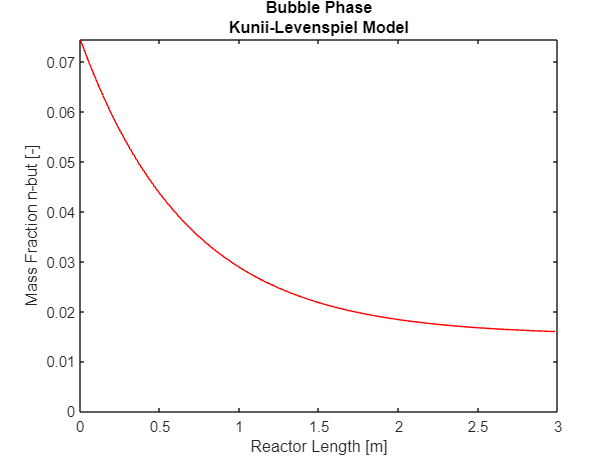

y_bubble=zeros(NP,NS);
y_cloud=zeros(NP,NS);
y_emulsion=zeros(NS,1);

for i=1:NP
    for k=1:NS
        j=1;
            y_bubble(i,k)=y(NTOT*(j-1)+NS*(i-1)+k);
        j=2;
            y_cloud(i,k)=y(NTOT*(j-1)+NS*(i-1)+k);
        j=3;
            y_emulsion(k)=y(NTOT*(j-1)+k);
    end
end

figure(1)
plot(z_star,y_bubble(:,1),'-r');
ylim([0 max(y_bubble(:,1))]);
xlabel('Reactor Length [m]');
ylabel('Mass Fraction n-but [-]');
tit=sprintf('Bubble Phase\nKunii-Levenspiel Model');
title(tit);

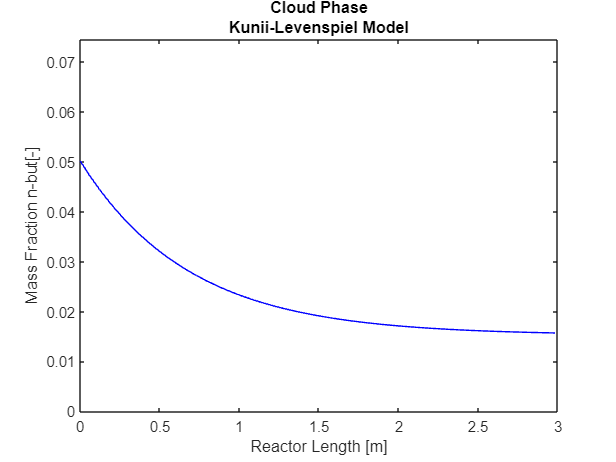


figure(2)
plot(z_star,y_cloud(:,1),'-b')
ylim([0 max(y_bubble(:,1))]);
xlabel('Reactor Length [m]');
ylabel('Mass Fraction n-but[-]');
tit=sprintf('Cloud Phase\nKunii-Levenspiel Model');
title(tit);

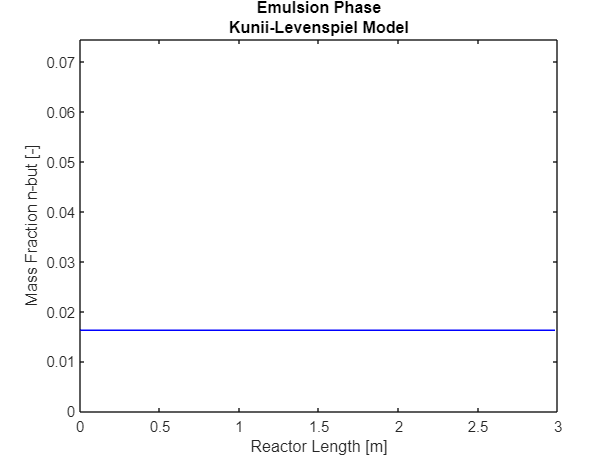

y_emulsion_plot = ones(NP,1)*y_emulsion(1); 
figure(3)
plot(z_star,y_emulsion_plot,'-b')
ylim([0 max(y_bubble(:,1))]);
xlabel('Reactor Length [m]');
ylabel('Mass Fraction n-but [-]');
tit=sprintf('Emulsion Phase\nKunii-Levenspiel Model');
title(tit);

youtletNbut=(v_mf*y_emulsion(1)*V_emulsion+ v_bubble*y_bubble(end,1)*V_bubble)/(v_0*V_reactor);
youtletMA=(v_mf*y_emulsion(3)*V_emulsion+ v_bubble*y_bubble(end,3)*V_bubble)/(v_0*V_reactor);
conversion=(omega_0(1)-youtletNbut)/omega_0(1);
selectivity=(youtletMA/MW(3))/((omega_0(1)-youtletNbut)/MW(1));
yield=conversion*selectivity;

fprintf("conversion: %f \n",conversion*100)

conversion: 78.520784 


fprintf("selectivity: %f \n",selectivity*100)

selectivity: 57.666729 


fprintf("yield: %f \n",yield*100)

yield: 45.280368 


Ctot = P0/8.314/T0; % mol/m3
total_molar_flowrate = Ctot*v_0; % mol/s/m2
bubble_molar_flowrate = Ctot*v_bubble*delta; % mol/s/m2
molar_fraction = bubble_molar_flowrate/total_molar_flowrate*100;

fprintf("fraction of molar gas flow rate in the bubble phase: %f %% \n",molar_fraction)

fraction of molar gas flow rate in the bubble phase: 98.876289 % 
